%notation consistent with :
%Polyzou, W., & Bulut, F. (2013). Wavelet Methods in Field Theory. Few-Body Systems, 55(5-7), 561–566. doi:10.1007/s00601-013-0735-9 
  

% dB_K, kmax+1, xstep 
[w,x] = wpfun('db5',3,5); xstep = x(2);
fprintf("dbK\nsupport: [%d, %d] \npoints: %d\nxstep: %f",min(x), max(x), length(x), xstep)

dbK
support: [0, 9] 
points: 290
xstep: 0.031142

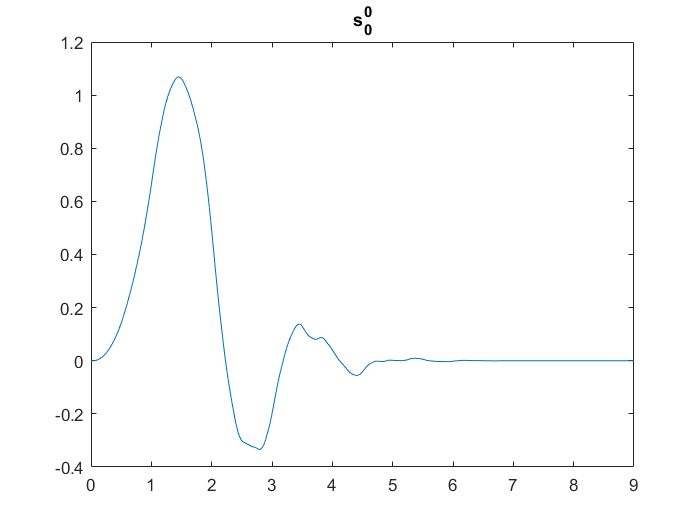

plot(x, w(1,:)); title('s^0_0'); 

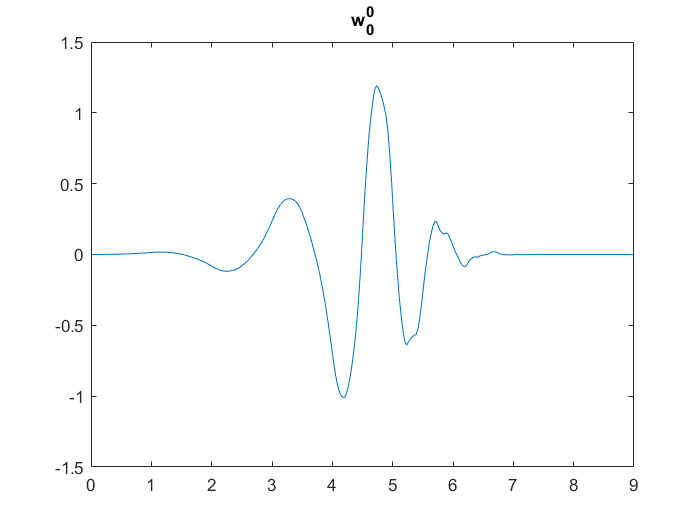

plot(x, w(2,:)); title('w^0_0'); 

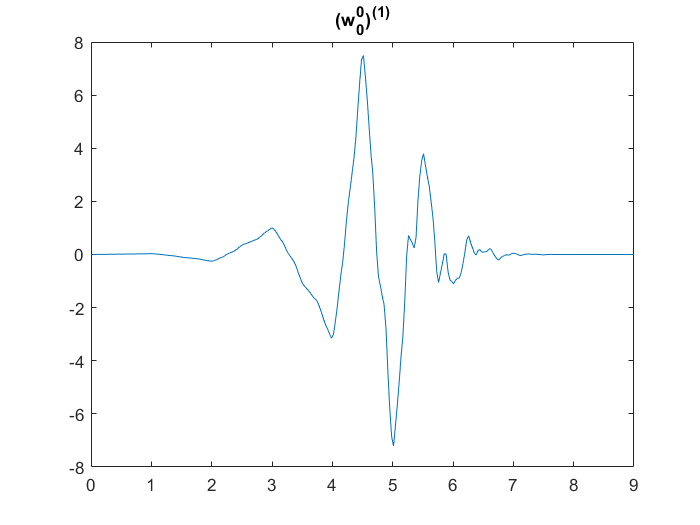

w00dash = gradient(w(2,:))/xstep;
w00ddash = gradient(w00dash)/xstep;
plot(x, w00dash); title('(w^0_0)^{(1)}');

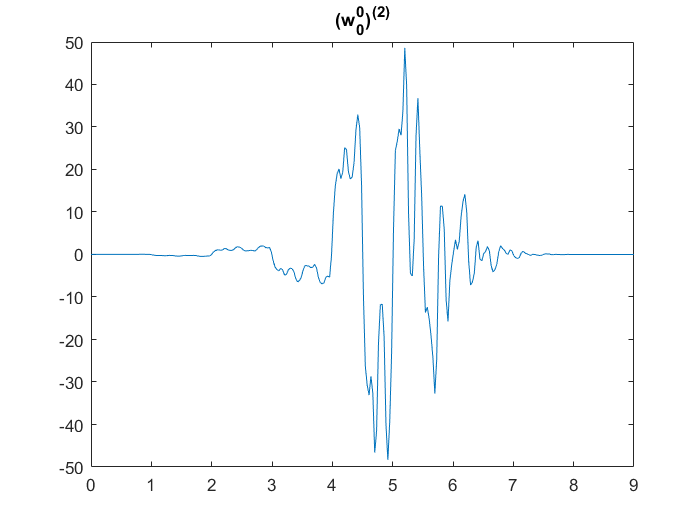

plot(x, w00ddash); title('(w^0_0)^{(2)}');

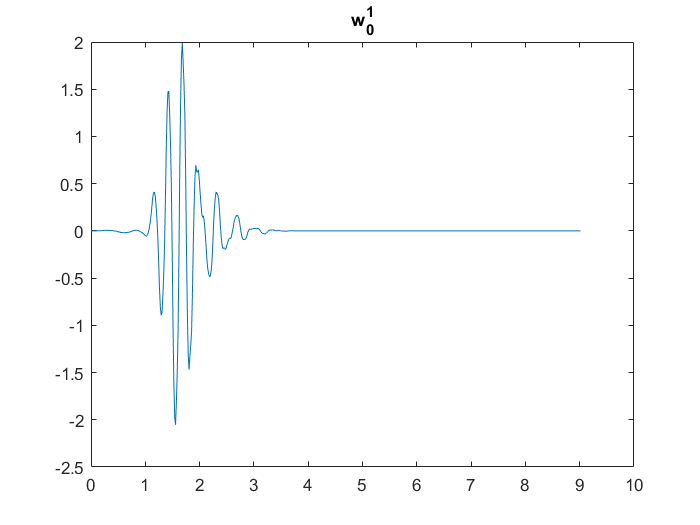

%always translate n times THEN scale k times
[w10, x10] = DT(w(3,:), x,1,0);
plot(x10, w10); title('w^1_0'); %1/2[n, 2K-1+n]

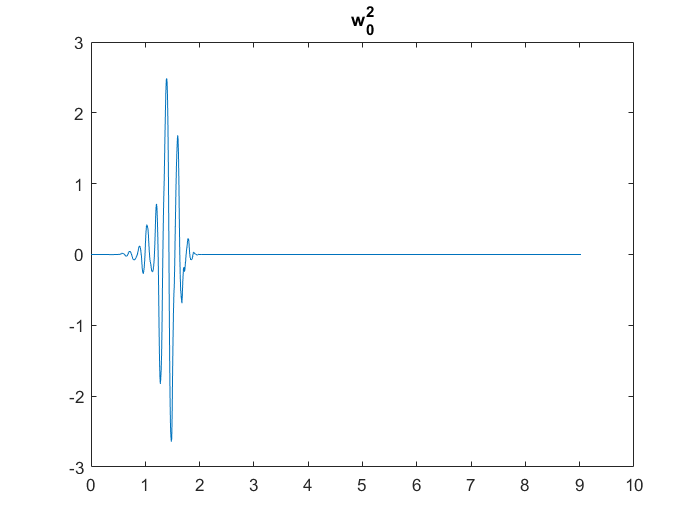

[w20, x20] = DT(w(4,:), x,2,0);
plot(x20, w20); title('w^2_0'); 

% s is the mother scaling fn PHI;  
% w is the mother wavelet fn PSI;
fprintf("<s|s> = %f",trapz(w(1,:).*w(1,:))*xstep);

<s|s> = 0.996540

fprintf("<w|w> = %f",trapz(w(2,:).*w(2,:))*xstep);

<w|w> = 0.996552

fprintf("<s|w> = %f",trapz(w(1,:).*w(2,:))*xstep);

<s|w> = -0.004683

fprintf("<w|w'> = %f",trapz(w(2,:).*w00dash)*xstep); 

<w|w'> = -0.000000

fprintf("<w|w''> = %f", trapz(w(2,:).*w00ddash)*xstep);

<w|w''> = -26.430826

fprintf("<w10|w10> = %f",trapz(w10.*w10)*(x10(2) - x10(1))); 

<w10|w10> = 0.996892

function [DTw, DTx] = DT(w,x,k,n)   
    %keep n <= (2K - 1)(2^k - 1)
    DTw = w;
    DTx = x+n;
    
    DTw = 2^(k/2)*DTw;
    DTx = DTx/(2^k);
    
    newxstep = DTx(2) - DTx(1);
    Lpad = round(DTx(1) / newxstep);
    
    DTx = wextend('1', 'asymw', DTx, length(DTx)*(2^k - 1), 'r');
    
    DTw = [DTw , zeros(1,(length(DTx) - length(DTw)))];
    DTw = circshift(DTw, Lpad); DTw(1:Lpad) = zeros(1, Lpad);   
    DTx = wextend('1', 'asymw', DTx, Lpad, 'l');
    
    DTx = DTx(1:length(DTw));
    
end

function [wd, xd] = singlediff(w, x)
    wd = gradient(w)/(x(2) - x(1));
    xd = x;
end

function [wdd, xdd] = doublediff(w, x)
    wd = gradient(w)/(x(2) - x(1));
    wdd = gradient(wd)/(x(2) - x(1));
    xdd = x;
end
